Scientific Computing 

Assignment 1

% question 1.a
% overflow test
% single test
clear;
testSingle = single(2);
testDouble = 2;
iteratorSingle = 0;
iteratorDouble = 0;
%test single
while (iteratorSingle >= 0)
    if testSingle == inf
        break;
    end
    testSingle = testSingle * 2;
    iteratorSingle = iteratorSingle + 1;
    
end
%test double
while (iteratorDouble >= 0)
    if testDouble == inf
        break;
    end
    testDouble = testDouble * 2;
    iteratorDouble = iteratorDouble + 1;
    
end
fprintf('the single bundary is:');
display(iteratorSingle);
fprintf('the double bundary is:');
display(iteratorDouble);

according to matlab document, if the float number overflow, it will be shown as infinite

the single number bundary is 2 to 127

the double number bundary is 2 to 1023

% question 1.b
% divide test
clear;
divByZero = 10/0;
divByInf = 10/inf;
zeroDivZero = 0/0;
fprintf('10 divided by zero is %g', divByZero);
fprintf('10 divided by infinite is %g', divByInf);
fprintf('0 divided by zero is %g', zeroDivZero);

% question 1.c
% NaN test
clear;
ntest = NaN;
divByNaN = 10 / ntest;
NaNDiv = ntest / 10;
addByNaN = 10 + ntest;
expByNan = 2^ntest;
fprintf('10 divided by NaN is %g', divByNaN);
fprintf('NaN divide 10 is %g', NaNDiv);
fprintf('10 add NaN is %g', addByNaN);
fprintf('2 to the NaN exponential is %g', expByNan);

it seems the result of any arithmetic operation between a number and NaN is NaN

% question 1.d
% inf comparation
clear;
a = inf;
c = 10/0;%infinite
b = NaN;
d = 0/0;%NaN
testArrWithoutNaN = [inf, 1, -1, 2, c];
testArrWithNaN = [inf, 1, -1, 2, c, NaN, b];
sortedNoNaN = sort(testArrWithoutNaN);
sortedNan = sort(testArrWithNaN);
display(sortedNoNaN);
display(sortedNan);
%comparation between infinite
fprintf('start compare 10/0 with infinite');
if a > inf
    fprintf('10/0 is bigger than infinite');
elseif a < inf
    fprintf('10/0 is smaller than infinite');
elseif a == inf
    fprintf('10/0 is equal to infinite');
else
    fprintf('cannot compare between inf');
end
%comparation between inf and number
fprintf('start compare 2 with inf');
if  2 > inf
    fprintf('2 is bigger than infinite');
elseif 2 < inf
    fprintf('2 is smaller than infinite');
elseif 2 == inf
    fprintf('2 is equal to infinite');
else
    fprintf('can compare between inf');
end
%test whether inf is nan
if isnan(10/0)
    fprintf('infinite is nan');
else
    fprintf('infinite is not nan');
end
    
    



NaN can't be compared with NaN, should use method ''isnan'' instead

% question 2
% 2.1
% do double first
clear;
dpi = pi;
dt = 1 / sqrt(3);
iteratordt = zeros(30);
approxPiDt = zeros(30);
relErrDouble = zeros(30);
for i = 1:30
    dt = (hypot(1,dt) -1) / dt;
    approxPiDt(i) = 6 * 2^i * dt;
    relErrDouble(i) = abs(dpi - approxPiDt(i)) / dpi;
    iteratordt(i) = i; 
end

% do single now
spi = single(pi);
st = single(1 / sqrt(3));
iteratorst = single(30);
approxPiSt = zeros(30);
relErrSingle = zeros(30);
for i = single(1:30)
    st = (hypot(single(1),st) - single(1)) / st;
    approxPiSt(i) = single(6) * single(2)^i * st;
    relErrSingle(i) = abs(dpi - approxPiSt(i)) / spi;
    iteratorst(i) = i; 
end


% plot
figure(1);
plot(iteratordt , approxPiDt, 'ro-', iteratorst, approxPiSt, 'bs-');
ylim([2.5 3.5]);
title('Approximate value');
xlabel('number of iteration');ylabel('value of Pi');
legend('approximate value in double', 'approximate value in single', 'location', 'NorthEast');

figure(2);
loglog(iteratordt , relErrDouble, 'ro-', iteratorst, relErrSingle, 'bs-');
%set(gca, 'ydir', 'reverse');
title('relative error');
xlabel('number of iteration');ylabel('relative error');
legend('relative error in double', 'relative error in single', 'location', 'NorthWest');


2.1b

when i is large, the roundoff error caused by catastrophic cancellation may cause the error. By subtraction 1- t^2, since 1 and t^2 has widely differing magnitude, the result lost most of digits and equals 1.

% question 2.2
clear;
t = 1 / sqrt(3);
approxPiT = zeros(2000);
relErr = zeros(2000);
iterator = zeros(2000);
for i = 1: 2000
    t = 1 / (hypot(1/t, 1) + 1/t);
    iterator(i) = i;
    approxPiT(i) = 6 * 2^i * t;
    relErr(i) = abs(pi - approxPiT(i)) / pi;
end

% plot
figure(1);
plot(iterator , approxPiT, 'ro');
ylim([3.1415926 3.1415927]);

title('Approximate value');
xlabel('number of iteration');ylabel('value of Pi');
legend('approximate value of improved equation','location', 'NorthEast');

figure(2);
loglog(iterator , relErr, 'ro-');
xlim([0 1e3]);
title('relative error');
xlabel('number of iteration');ylabel('relative error');
legend('relative error','location', 'NorthWest');


I think I have get the highest possible accuracy, since I cause overflow due to 6*2^i, i =1021 should be the best acc

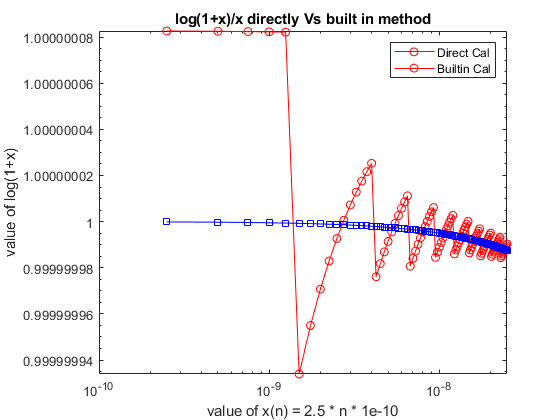

% problem 3
% 3.1
clear;
direct_cal = zeros(100);
builtin_cal = zeros(100);
taylor_cal = zeros(100);

relErrDirect = zeros(100);
relErrBuiltin = zeros(100);
relErrTaylor = zeros(100);

x = zeros(100);
for n = 1:100
    x(n) = 2.5 * n * 1e-10;
    direct_cal(n) = log(1+x(n))/x(n);
    builtin_cal(n) =  log1p(x(n))/x(n);
    taylor_cal(n) = taylor_log1p(x(n))/x(n);
    relErrDirect(n) = abs(direct_cal(n) - builtin_cal(n) / builtin_cal(n));
    relErrBuiltin(n) = abs(builtin_cal(n) - builtin_cal(n) / builtin_cal(n));
    relErrTaylor(n) = abs(taylor_cal(n) - builtin_cal(n) / builtin_cal(n));
end


figure(1);
loglog(x, direct_cal,'ro-',x , builtin_cal, 'bs-');
title('log(1+x)/x directly Vs built in method');
xlabel('value of x(n) = 2.5 * n * 1e-10');ylabel('value of log(1+x)');
%set(gca,'xdir','reverse');
legend('Direct Cal', 'Builtin Cal', 'location', 'NorthEast');

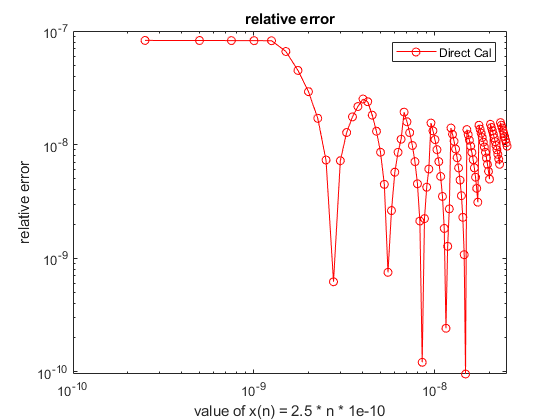


figure(2);
loglog(x, relErrDirect,'ro-');
title('relative error');
xlabel('value of x(n) = 2.5 * n * 1e-10');ylabel('relative error');
%set(gca,'xdir','reverse');
legend('Direct Cal','location', 'NorthEast');

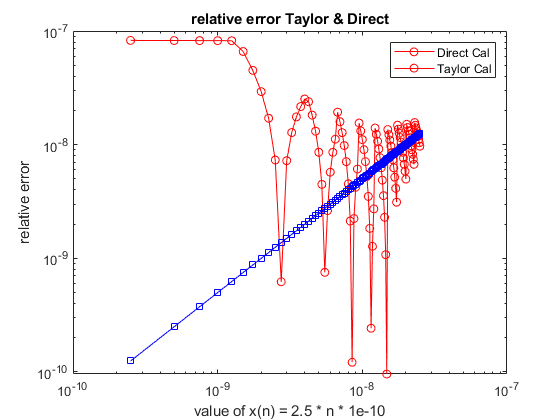




figure(3);
loglog(x, relErrDirect,'ro-',x , relErrTaylor, 'bs-');
title('relative error Taylor & Direct');
xlabel('value of x(n) = 2.5 * n * 1e-10');ylabel('relative error');
xlim([1e-10 1e-7]);
%set(gca,'xdir','reverse');
legend('Direct Cal', 'Taylor Cal', 'location', 'NorthEast');

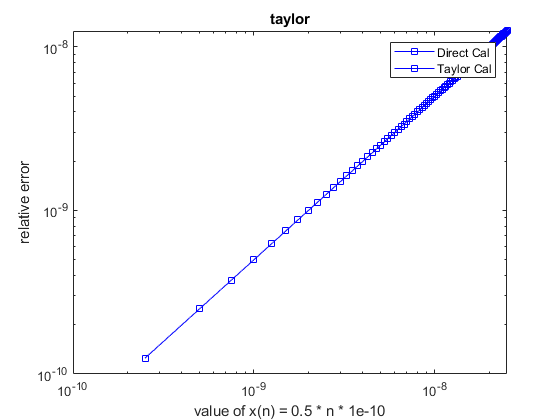


figure(4);
loglog(x , relErrTaylor, 'bs-');
title('taylor');
xlabel('value of x(n) = 0.5 * n * 1e-10');ylabel('relative error');
%set(gca,'xdir','reverse');
legend('Direct Cal', 'Taylor Cal', 'location', 'NorthEast');

% Problem 4
% calculate double
u_d = eps('double') / 2;
x0_d = pi / 4;
exact_ans_d = -sin(x0_d);
h_d = logspace(-15, 0, 50);


sec_deri_double = (sin(x0_d + h_d) - 2*sin(x0_d) + sin(x0_d - h_d))./h_d.^2;


% calculate relative error
err_double = abs((sec_deri_double - exact_ans_d)/ exact_ans_d);

% calculate estimated errors
trunc_d = h_d.^2/12;
round_d = u_d./h_d.^2;

% plot
figure(1);
loglog(h_d, err_double, 'or', h_d, trunc_d, '--r');
hold on;
%loglog(h_d, err_double, 'sb', h_d, trunc2_d, '--b');
loglog(h_d, round_d, '-g');

legend('finite differences', 'Trunctation error', ...
        'Rounding error', 'Location', 'North');
%axis([1e-16, 1 1e-12, 1]);
xlabel('h'); ylabel('Relative Error');
title('Double-precision finite derivative');

% caluculate single
u_s = eps('single')/2;
x0_s = single(pi/4);
exact_ans_s = single(-sin(x0_s));
h_s = single(logspace(-8, 0, 50));

sec_deri_single = (sin(x0_s + h_s) -2*sin(x0_s) + sin(x0_s - h_s))./h_s.^2;

% relative error
err_single = abs((sec_deri_single - exact_ans_s) / exact_ans_s);

% estimate error
trunc_s = h_s.^2/12;
round_s = u_s./h_s.^2;

figure(2);
loglog(h_s, err_single, 'or', h_s, trunc_s, '--r');
hold on;
%loglog(h_d, err_double, 'sb', h_d, trunc2_d, '--b');
loglog(h_s, round_s, '-g');

legend('finite differences', 'Trunctation error', ...
        'Rounding error', 'Location', 'North');
%axis([1e-8, 1 1e-6, 1]);
xlabel('h'); ylabel('Relative Error');
title('Single-precision finite derivative');

function taylorApprox = taylor_log1p(x)
    taylorApprox = x - (x^2)/2 + (x^3)/3;   
end
